# Sampled Feedback System for Locally Linearized Franka Emika Panda

Add Path

clear;clc;
close all
addpath("PandaDyn\")
addpath("Dynamics\")
addpath("..\ReadYAML\")
addpath("..\")
config=ReadYaml("Configuration\FrankaEmikaPanda.yaml");

The system follows


$$M\left(\vec{q}_{d}\right) \ddot{\vec{q}} + G \left( \vec{q}_{d} \right) = - K_{p} \left( \hat{q} - \vec{q}_{d} \right) - K_{d} \dot{\hat{q}} - f_{\text{Linearized}} \left( \dot{\vec{q}} \right),$$


where friction follows


$$f_{\text{Linearized}}^{j} (\dot{q}_{j})= \frac{\varphi_{1,j} \varphi_{2,j} e^{-\varphi_{2,j} \varphi_{3,j}}}{\left( 1 + e^{-\varphi_{2,j} \varphi_{3,j}} \right)^{2}} \dot{q}_{j}.$$


## Configurations

SolverOpt

SolverOpt.initial_condition=config.StateInitial';
SolverOpt.end_time=config.SimulationTime;
SolverOpt.sampling_time=config.ts;
SolverOpt.ratio=config.ratio;
SolverOpt.ode_setting=odeset('RelTol', config.ODE_RelTol, ...
    'AbsTol', config.ODE_AbsTol);

Other parameters

TargetAngle=config.TargetAngle';
Kp=diag(config.Kp);
Kd=diag(config.Kd);

## Digital Feedback Control Case

System ODE and Input Function

SysODE=@(t,State,Torque)LinearizedODE(t,State,TargetAngle,Torque);
InputFun=@(state)PDTorque(Kp,Kd,state,TargetAngle);

Simulation

sol=SampledControlSolver(SysODE,InputFun,SolverOpt)

历时 3.564647 秒。


sol = 包含以下字段的 struct :
                  ts: 0.0080
                 dim: 7
                  dt: 8.0000e-06
    sampling_moments: [1×126 double]
            duration: [1×125001 double]
       state_history: [14×125001 double]
       state_sampled: [14×126 double]
       input_history: [7×125001 double]


% sol.state_history(:,end)
% sol.input_history(:,end)

## Visualization for Digital Feedback Control

Collect Data for Visualization

eTimeHistoryDigital=sol.state_history(1:7,:)-TargetAngle;

$e-t$ Diagram

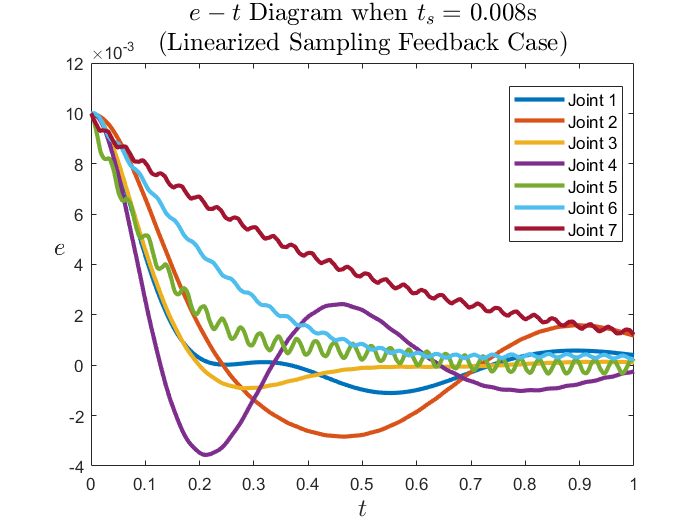

plot(sol.duration,eTimeHistoryDigital,"LineWidth",2.5)
title(["$$e-t$$ Diagram when $$t_s=$$ "+num2str(sol.ts)+"s","(Linearized Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$e$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

$\dot{e}-t$ Diagram

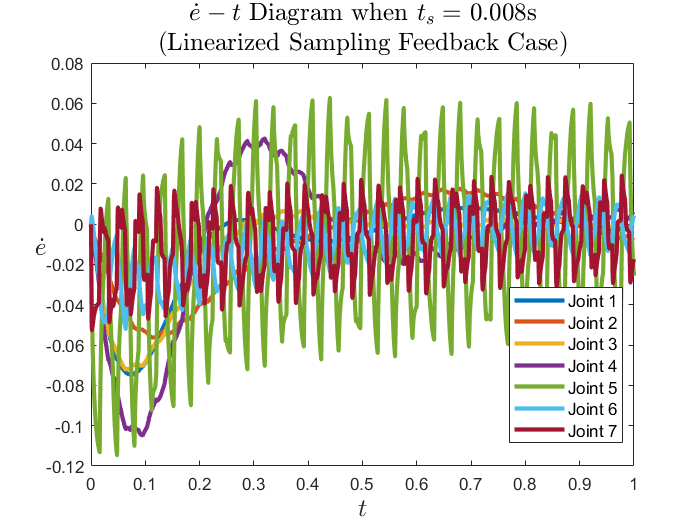

plot(sol.duration,sol.state_history(8:14,:),"LineWidth",2.5)
title(["$$\dot{e}-t$$ Diagram when $$t_s=$$ "+num2str(sol.ts)+"s","(Linearized Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

$\tau-t$ Diagram

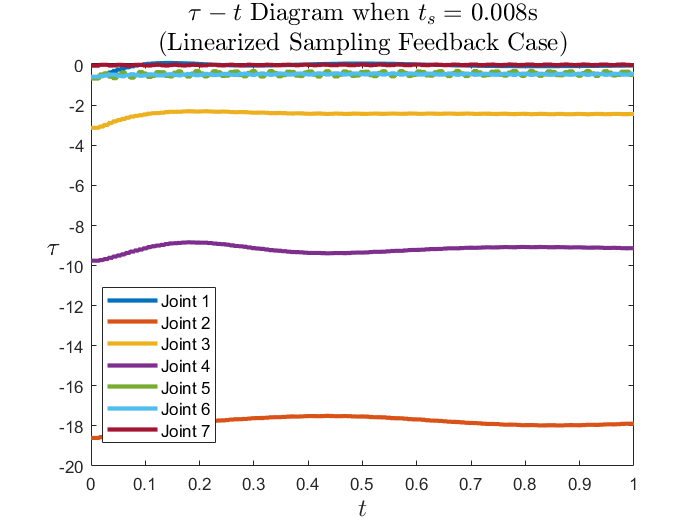

plot(sol.duration,sol.input_history,"LineWidth",2.5)
title(["$$\tau-t$$ Diagram when $$t_s=$$ "+num2str(sol.ts)+"s","(Linearized Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\tau$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Fontsize",10,"Location","best")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

## Visualization in Cartesian Space

MDH parameter of Franka Emika Panda

mdl_panda

Trajectory of End Effector

EndEffectorLocLinearizedDigital=panda.fkine(sol.state_history(1:7,:)').transl';

Target of End Effector

EndEffectorLocTarget=panda.fkine(TargetAngle).transl';

End Effector Trajectory

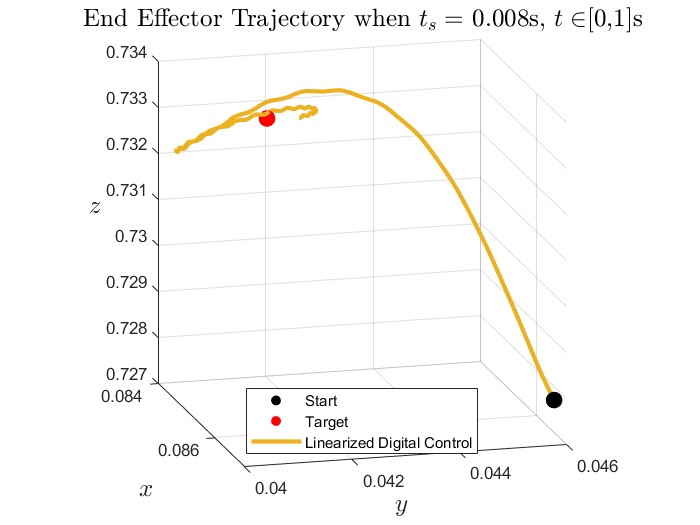

scatter3(EndEffectorLocLinearizedDigital(1,1),EndEffectorLocLinearizedDigital(2,1),EndEffectorLocLinearizedDigital(3,1),100,"black","filled","o")
hold on
scatter3(EndEffectorLocTarget(1),EndEffectorLocTarget(2),EndEffectorLocTarget(3),100,"Red","filled","o")
plot3(EndEffectorLocLinearizedDigital(1,:),EndEffectorLocLinearizedDigital(2,:),EndEffectorLocLinearizedDigital(3,:),"LineWidth",2.5)
hold off
title("End Effector Trajectory when $$t_s=$$ "+num2str(sol.ts)+ ...
    "s, $$t \in$$[0,"+num2str(SolverOpt.end_time)+"]s", ...
    "FontSize",15,"Interpreter","latex")
view(75,15)
pbaspect([1 1 1])
legend("Start","Target","Linearized Digital Control","Location","south")
xlabel("$$x$$","Interpreter","latex","FontSize",15)
ylabel("$$y$$","Interpreter","latex","FontSize",15)
zlabel("$$z$$","Interpreter","latex","FontSize",15,"Rotation",pi/2)
grid on

## Save Data

save("Data\StateTimeHistory_Linearized_"+ ...
    datestr(datetime("today"),"yyyy_mm_dd")+".mat","sol")

Remove Path

rmpath("Dynamics\")
rmpath("PandaDyn\")
rmpath("..\ReadYAML\")